# ASSIGNMENT 2

Gianpaolo Mastroiacovo()

Antonio Di Giovanni()

Data(26/04/2021)

## Exercise 2.1)

#### *a)*

%P = [0.20 0 0.15 0.10 0.05 0 0 0 0.35 0.15];
P = [0.2 0.15 0.1 0.05 0.35 0.15]

P =     0.2000    0.1500    0.1000    0.0500    0.3500    0.1500


N = [1 3 4 5 9 10];

Prob = [0.20 0 0.15 0.10 0.05 0 0 0 0.35 0.15];
Distr_X = makedist('Multinomial','Probabilities',Prob);
y = cdf(Distr_X, N) %Used to create a cumulative distribution function

y =     0.2000    0.3500    0.4500    0.5000    0.8500    1.0000


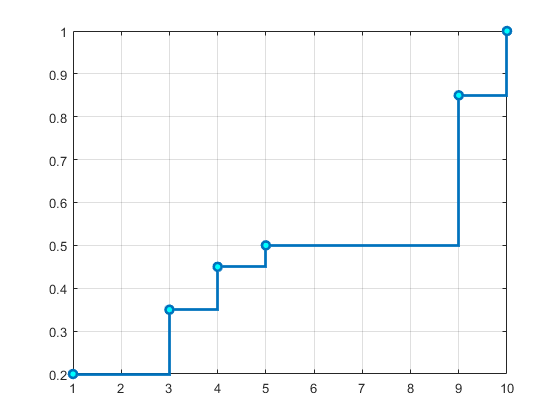

%p = plot(N,y,'ro');
stairs(N,y,'LineWidth',2,"Marker",'o',"MarkerFaceColor",'c')
hold on
grid
hold off


%y = pdf(Distr_X, N);
%X = random(Distr_X,10^6,1); % What does draw a distr. mean in this case?
%cdfplot(X); %Bisogna fare un plot senza tener conto di un'estrazione X. Come disegnare un grafico simile a quello sotto?

b)

meanX = sum(N.*P)

meanX = 5.9500

varX = sum((N-meanX).^2)/length(N) %Should we use Sample or Population variance?

varX = 10.6025

#### *Old: (Da cancellare)*

%varX = var(X)
%meanX = mean(X)

## Exercise 2.2) 

#### *a)*


$$\begin{array}{l}
\max_{\textrm{Solar},\textrm{Wind}} \;\;\;\;\textrm{Solar}\cdot P_{\textrm{solar}} +\textrm{Wind}\cdot \;P_{\textrm{wind}} \\
s\ldotp t\ldotp \\
\;\;\;\;\;\;\;\;\;\;\textrm{Solar}+\textrm{Wind}=1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Solar},\textrm{Wind}\in \left\lbrace 0,1\right\rbrace 
\end{array}$$


#### *b)*

Solar = binvar(3,1);
Wind = binvar(3,1);

% Definition of Profits
Wind_Profit = [10; 50; 80];
Solar_Profit = [100; 60; 10];

Cons = Solar + Wind == 1;

DeterministicResult = [];
for i = 1:3
obj = Solar(i)' * Solar_Profit(i) + Wind(i)' * Wind_Profit(i);

ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

res = optimize(Cons, -obj, ops);
DeterministicResult = [DeterministicResult; value(obj)];
end


value(Solar)

ans =      1
     1
     0


value(Wind)

ans =      0
     0
     1


value(DeterministicResult)

ans =    100
    60
    80


#### *c)* 


$$\begin{array}{l}
\max_{\textrm{Solar},\textrm{Wind}} \;\;\;\;\frac{1}{3}\sum_{i=1}^3 \textrm{Solar}*{P^{\;\textrm{solar}} }_i +\textrm{Wind}*{P^{\;\textrm{wind}} }_i \\
s\ldotp t\ldotp \\
\;\;\;\;\;\;\;\;\;\;\textrm{Solar}+\textrm{Wind}=1\;\;\;\;\;\;\;\;\;\;\textrm{Solar},\textrm{Wind}\in \left\lbrace 0,1\right\rbrace 
\end{array}$$


%A = unidrnd(3,3,1)
% Definition of Decision Variables
Solar = binvar(1);
Wind = binvar(1);

% Definition of Profits
Wind_Profit = [10; 50; 80];
Solar_Profit = [100; 60; 10];

Cons = Solar + Wind == 1;

obj = mean(Solar * Solar_Profit + Wind * Wind_Profit);

ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

result = optimize(Cons, -obj, ops);

value(Solar)

ans = 1

value(Wind)

ans = 0

value(obj)

ans = 56.6667


% Add b) before the code above.

AverageScenarioSolution = mean(DeterministicResult)

AverageScenarioSolution = 80

In this case, the average of the solutions is higher than the solution of the expected profit maximization problem, because we are making a decision already the deterministic value of the profits (DA RIAGGIUSTARE).

## Exercise 2.3)

#### *a)*

$E\left(W_t \right)=\sum_{i=1}^n x_i \cdot \left(1+E\left(R_i \right)\right)$  RIGA DA CANCELLARE


$$\begin{array}{l}
\max_{x_1 ,\ldotp \ldotp \ldotp ,x_n } \;\sum_{i=1}^n x_i \cdot \left(1+E\left(R_i \right)\right)\\
s\ldotp t\\
\;\;\;\;\;\;\;\;\sum_{i=1}^n x_i \le {\;W}_0 \;\;\;\;\;\;x\in \Re \;
\end{array}$$


#### *b)*


$$\begin{array}{l}
\mu_i =1+E\left(R_i \right)\\
\mu_{\max } =\max \;\mu_i \;\;\;\;\;i=1,2,\ldotp \ldotp \ldotp ,n\;
\end{array}$$


Not having additional constraints, in this case the function is maximized when the entire capital is invested in the asset which yields the highest return ($\mu_{\max }$), we will call the capital assigned to this asset $x_{\max } \ldotp$


$$\max_x \;E\left(W_t \right)=x_{\max } \cdot \mu {\;}_{\max }$$


#### *c)*


$$\begin{array}{l}
\max_{x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n } \;\;\sum_{i=1}^n x_i \cdot \mu_i \\
s\ldotp t\\
\;\;\;\;\;\;\;\;\sum_{i=1}^n x_i \le W_0 \\
\;\;\;\;\;\;\;\;\;x^T \Sigma x\le v
\end{array}$$


#### *d)*

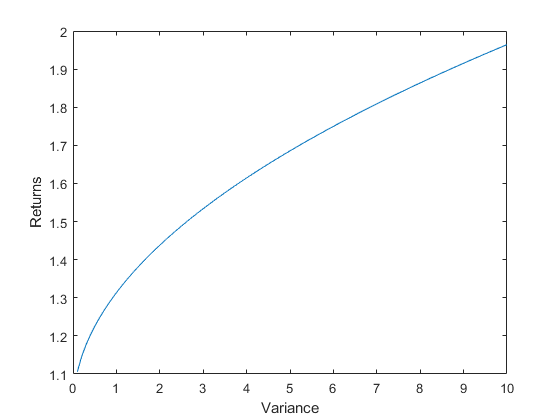

Cov = [0.017, 0.003, 0.001; 0.003, 0.006, 0.004; 0.001, 0.004, 0.063];
W_0 = 1;
mu = [1.026; 1.008; 1.074];
v = [0.1:0.1:10];
Results = [];

for i = 1:length(v)
x = sdpvar(3,1);

Cons = sum(x)<= W_0;
Cons = [Cons, (x'*Cov)*x <= v(i)];

obj = x'*mu;
ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

res = optimize(Cons, -obj, ops);
Results = [Results, value(obj)];
end

x = v;
y = Results;
figure
plot(x,y);
xlabel('Variance');
ylabel('Returns');

We decided to use v as independent variable as this is the customary way it is done in Markowitz Portfolio theory.

## Exercise 2.4)


$$\begin{array}{l}
\min_{x_1 ,x_2 ,x_3 ,z,y} \;\;\;z\\
s\ldotp t\ldotp \\
\;\;\;\;\;\;\;\;\begin{array}{l}
x_1 +\textrm{x2}\ge \textrm{x3}\\
x_1 ,\textrm{x2},\textrm{x3}\ge 0\\
3\textrm{x1}\ge 2\\
z\ge 3x_1 -2\\
z\ge 4x_2 \\
z\ge y\\
y\ge 2x_3 \\
y\ge x_1 +x_2 -x_3 
\end{array}
\end{array}$$


%Check if two variables are necessary

#### *b)*

% Decision Variables
z = sdpvar;
y = sdpvar;
x1 = sdpvar;
x2 = sdpvar;
x3 = sdpvar;

% Objective Function
obj = z;

%Constraints
Cons = x1 + x2 >= x3;
Cons = [Cons, x1 >= 0];
Cons = [Cons, x2 >= 0];
Cons = [Cons, x3 >= 0];
Cons = [Cons, x1 >= 2/3];
Cons = [Cons, z >= 3*x1-2];
Cons = [Cons, z >= 4*x2];
Cons = [Cons, z >= y];
Cons = [Cons, y >= 2*x3+1];
Cons = [Cons, y >= x1+x2+x3];

%Options
ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

% Solve the problem
DeterministicResult = optimize(Cons, obj, ops);      % The optimize function always minimizes

%value(z)
%value(y)

%value(x1)
%value(x2)
%value(x3)

## Exercise 2.5)

#### *a)* (controllare se y va inserita tra le variabili di min)


$$\begin{array}{l}
\min_{x_1 ,x_2 ,x_3 ,y} \;\;\;{3x}_1 -{4x}_2 +x_3 \\
s\ldotp t\ldotp \\
\;\;\;\;\;\;\;\;\;\;\begin{array}{l}
x_1 +x_3 \ge x_2 \\
y\le 2\\
{y\ge \;x}_1 +x_2 \\
y\ge x_3 \;\\
{3x}_3 \le 5\\
x_1 \;,x_{2\;} ,x_3 \ge 0
\end{array}
\end{array}$$


#### *b)* 

% Decision Variables
y = sdpvar;
x1 = sdpvar;
x2 = sdpvar;
x3 = sdpvar;

% Objective Function
obj = 3 * x1 - 4 * x2 + x3;

%Constraints
Cons = x1 + x3 >= x2;
Cons = [Cons, x1 >= 0];
Cons = [Cons, x2 >= 0];
Cons = [Cons, x3 >= 0];
Cons = [Cons, 3 * x3 <= 5];
Cons = [Cons, y <= 2];
Cons = [Cons, y >= x1 + x2];
Cons = [Cons, y >= x3];

%Options
ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

% Solve the problem
DeterministicResult = optimize(Cons, obj, ops);       % The optimize function always minimizes

value(obj)

ans = -5.1667

value(x1)

ans = 0.1667

value(x2)

ans = 1.8333

value(x3)

ans = 1.6667

value(y)

ans = 2